Bewegungsgleichung:

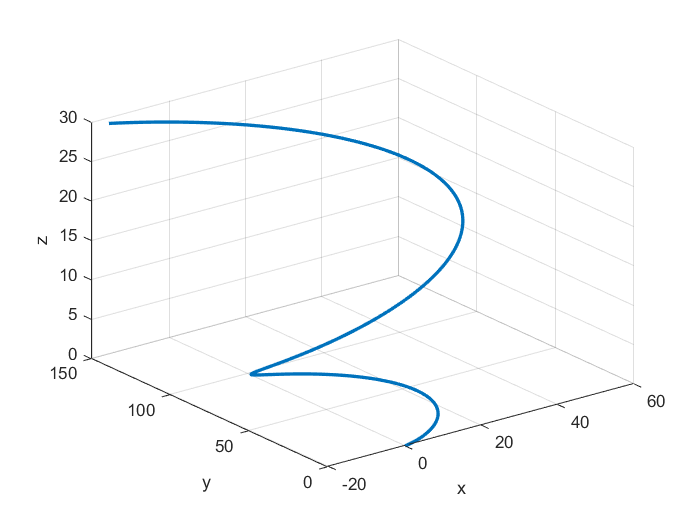

R_0 = [0; 0; 0];
V_0 = [0; 0; 0];
t = linspace(0, 20, 200);
A = [5 * cos(t/2); 5 * sin(t/2); 0.2 * ones(size(t/2))]; % Erhöhte Beschleunigung
V = cumtrapz(t/2, A, 2) + V_0;

R = R_0 + cumtrapz(t/2, V, 2) + 0.5 * cumtrapz(t/2, A, 2) .* t;
figure;
plot3(R(1,:), R(2,:), R(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

Gemessene Werte:

% R_measured = extract_every_third_column(R);
% figure;
% plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'LineWidth', 2);
% xlabel('x');
% ylabel('y');
% zlabel('z');
% grid on;

% Eingabe-Array erstellen (3 Zeilen, 200 Spalten)
eingabeArray = reshape(1:600, 3, 200);

% Parameter für die Verarbeitung
werteProSchritt = 5;
werteUeberspringen = 5;

% Größe des Eingabe-Arrays bestimmen
[zeilen, spalten] = size(R);

% Berechnung der Anzahl der Schritte
anzahlSchritte = ceil(spalten / (werteProSchritt + werteUeberspringen));

% Neues Array initialisieren
R_measured = [];

% Schleife für jeden Schritt
for schritt = 1:anzahlSchritte
    % Startindex für den aktuellen Schritt berechnen
    startIndex = (schritt - 1) * (werteProSchritt + werteUeberspringen) + 1;
    
    % Endindex für den aktuellen Schritt berechnen
    endeIndex = min(startIndex + werteProSchritt - 1, spalten);
    
    % Werte für den aktuellen Schritt aus dem Eingabe-Array extrahieren
    aktuelleWerte = R(:, startIndex:endeIndex);
    
    % Aktuelle Werte an das neue Array anhängen
    R_measured = [R_measured, aktuelleWerte];
end

% Ausgabe des neuen Arrays
R_measured

R_measured =          0    0.0189    0.0756    0.1699    0.3012    1.8277    2.1951    2.5911    3.0139    3.4617    6.5599    7.1237    7.6945    8.2699    8.8472   12.2030   12.7195   13.2169   13.6926   14.1442   16.2176   16.4377   16.6171   16.7541   16.8475   16.4291   16.1896   15.9008   15.5626   15.1754   11.8577   11.1488   10.3992    9.6108    8.7855    3.1897    2.1744    1.1433    0.0994   -0.9539   -7.2818   -8.3051   -9.3098  -10.2926  -11.2497  -16.2617  -16.9444  -17.5752  -18.1513  -18.6699
         0    0.0005    0.0035    0.0116    0.0272    0.4155    0.5506    0.7117    0.9004    1.1187    3.1358    3.6015    4.1068    4.6521    5.2380    9.6079   10.4758   11.3819   12.3250   13.3040   19.8459   21.0303   22.2359   23.4603   24.7009   32.3359   33.6137   34.8851   36.1471   37.3967   44.4655   45.5449   46.5886   47.5939   48.5584   53.3595   53.9769   54.5376   55.0403   55.4841   56.8673   56.8823   56.8362   56.7297   56.5636   54.3896   53.8475   53.2599   52.

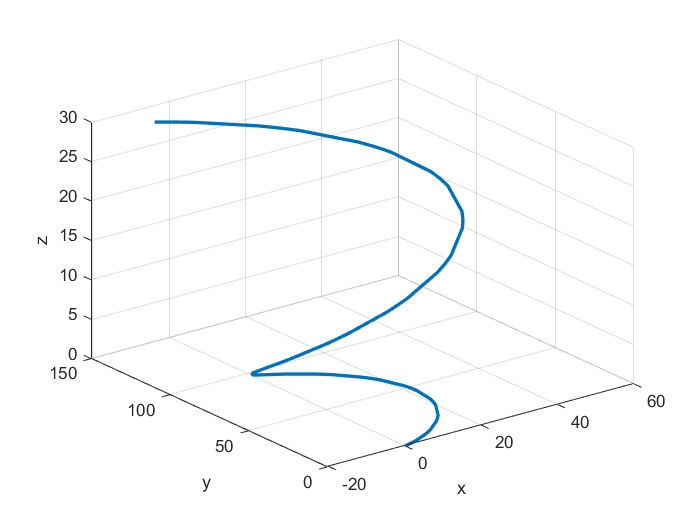


figure;
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

% y = awgn(R_measured,5);
% 
% figure;
% plot3(y(1,:), y(2,:), y(3,:), 'LineWidth', 2);
% xlabel('x');
% ylabel('y');
% zlabel('z');
% grid on;


R_measured(3,:)

ans =          0    0.0008    0.0030    0.0068    0.0121    0.0758    0.0917    0.1091    0.1280    0.1485    0.3030    0.3341    0.3667    0.4007    0.4364    0.6818    0.7280    0.7757    0.8250    0.8757    1.2121    1.2735    1.3363    1.4007    1.4666    1.8939    1.9704    2.0484    2.1280    2.2090    2.7272    2.8189    2.9120    3.0067    3.1030    3.7120    3.8188    3.9272    4.0370    4.1484    4.8484    4.9703    5.0938    5.2188    5.3453    6.1362    6.2733    6.4120    6.5521    6.6938


for i=1:length(R_measured(3,:))
    % Zufällige Werte zwischen -2 und 2 generieren
    randomValues = 4 * rand(1, 1) - 2;
    R_measured(3,i) = R_measured(3,i) + randomValues;
end
R_measured(3,:)

ans =    -1.0505    0.1242   -1.6310   -0.3719   -1.5685   -1.4751    1.2294   -0.7246    0.5422    2.0062    0.0330    1.1131    1.3991    0.1313    1.0583   -0.8792    2.4631   -0.4744   -0.1103    2.0671    1.1625    2.3493    0.9204    0.4925   -0.3844    2.5871    1.6887    1.8554    2.5674    0.4466    1.9904    3.9098    3.6978    1.5081    1.6236    2.0814    1.8501    3.6196    4.6593    5.0401    4.9732    3.4056    5.6209    3.7248    3.8825    4.5306    4.8414    5.0850    5.3371    5.9637


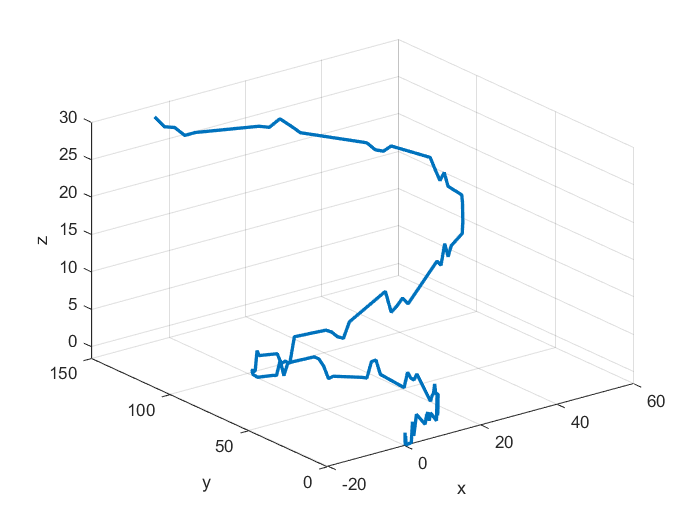

figure;
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

% Parameter für die Verarbeitung
werteProSchritt = 5;
werteUeberspringen = 5;

% Größe des Eingabe-Arrays bestimmen
[~, spalten] = size(t);

% Berechnung der Anzahl der Schritte
anzahlSchritte = ceil(spalten / (werteProSchritt + werteUeberspringen));

% Neues Array initialisieren
t_measured = [];

% Schleife für jeden Schritt
for schritt = 1:anzahlSchritte
    % Startindex für den aktuellen Schritt berechnen
    startIndex = (schritt - 1) * (werteProSchritt + werteUeberspringen) + 1;
    
    % Endindex für den aktuellen Schritt berechnen
    endeIndex = min(startIndex + werteProSchritt - 1, spalten);
    
    % Werte für den aktuellen Schritt aus dem Eingabe-Array extrahieren
    aktuelleWerte = t(startIndex:endeIndex);
    
    % Aktuelle Werte an das neue Array anhängen
    t_measured = [t_measured, aktuelleWerte];
end

% Ausgabe des neuen Arrays
t_measured

t_measured =          0    0.1005    0.2010    0.3015    0.4020    1.0050    1.1055    1.2060    1.3065    1.4070    2.0101    2.1106    2.2111    2.3116    2.4121    3.0151    3.1156    3.2161    3.3166    3.4171    4.0201    4.1206    4.2211    4.3216    4.4221    5.0251    5.1256    5.2261    5.3266    5.4271    6.0302    6.1307    6.2312    6.3317    6.4322    7.0352    7.1357    7.2362    7.3367    7.4372    8.0402    8.1407    8.2412    8.3417    8.4422    9.0452    9.1457    9.2462    9.3467    9.4472


% Gegebene 3D-Punkte (X, Y, Z)
% R_measured = 3x20
points = transpose(R_measured)

points =          0         0   -1.0505
    0.0189    0.0005    0.1242
    0.0756    0.0035   -1.6310
    0.1699    0.0116   -0.3719
    0.3012    0.0272   -1.5685
    1.8277    0.4155   -1.4751
    2.1951    0.5506    1.2294
    2.5911    0.7117   -0.7246
    3.0139    0.9004    0.5422
    3.4617    1.1187    2.0062



% Zeitpunkte für die Punkte (optional)
% t = 1x200
%t_measured = extract_every_third_column(t)
% time = 20x1
time = transpose(t_measured)

time =          0
    0.1005
    0.2010
    0.3015
    0.4020
    1.0050
    1.1055
    1.2060
    1.3065
    1.4070




% Berechnung der Geschwindigkeit
velocityX = diff(points(:, 1)) ./ diff(time);
velocityY = diff(points(:, 2)) ./ diff(time);
velocityZ = diff(points(:, 3)) ./ diff(time);

% Geschwindigkeitsvektor erstellen
% velocityVector = [VX1, VY1, VZ1;
%                   VX2, VY2, VZ2;
%                   VX3, VY3, VZ3;
%                   ...];
velocityVector = [velocityX, velocityY, velocityZ];

% Berechnung der Beschleunigung
accelerationX = diff(velocityVector(:, 1)) ./ diff(time(1:end-1));
accelerationY = diff(velocityVector(:, 2)) ./ diff(time(1:end-1));
accelerationZ = diff(velocityVector(:, 3)) ./ diff(time(1:end-1));

% Beschleunigungsvektor erstellen
accelerationVector = [accelerationX, accelerationY, accelerationZ];


% Ergebnis ausgeben
disp(velocityVector);

    0.1883    0.0047   11.6888
    0.5642    0.0300  -17.4645
    0.9377    0.0803   12.5276
    1.3072    0.1556  -11.9059
    2.5314    0.6439    0.1549
    3.6555    1.3452   26.9096
    3.9396    1.6020  -19.4424
    4.2069    1.8780   12.6046
    4.4561    2.1720   14.5669
    5.1378    3.3450   -3.2722
    5.6097    4.6342   10.7473
    5.6801    5.0272    2.8453
    5.7250    5.4261  -12.6140
    5.7441    5.8293    9.2239
    5.5650    7.2467   -3.2131
    5.1398    8.6361   33.2552
    4.9491    9.0153  -29.2278
    4.7332    9.3841    3.6229
    4.4929    9.7411   21.6648
    3.4384   10.8487   -1.5000
    2.1901   11.7848   11.8085
    1.7847   11.9956  -14.2178
    1.3638   12.1825   -4.2574
    0.9288   12.3445   -8.7252
   -0.6938   12.6613    4.9277
   -2.3826   12.7139   -8.9392
   -2.8740   12.6505    1.6589
   -3.3647   12.5571    7.0846
   -3.8530   12.4335  -21.1015
   -5.5019   11.7224    2.5601
   -7.0533   10.7397   19.0971
   -7.4581   10.3846   -2.1092
   -7.84

% Ergebnis ausgeben
disp(accelerationVector);

    3.7397    0.2510 -290.0749
    3.7161    0.5010  298.4209
    3.6768    0.7491 -243.1133
   12.1812    4.8584  120.0047
    1.8641    1.1630   44.3683
    2.8269    2.5555 -461.2022
    2.6594    2.7460  318.8670
    2.4799    2.9259   19.5252
    6.7830   11.6713 -177.4995
    0.7826    2.1379   23.2490
    0.7004    3.9106  -78.6244
    0.4469    3.9690 -153.8203
    0.1895    4.0118  217.2873
   -1.7822   14.1032 -123.7480
   -0.7051    2.3040   60.4765
   -1.8975    3.7726 -621.7060
   -2.1474    3.6702  326.8650
   -2.3915    3.5522  179.5162
  -10.4923   11.0199 -230.4897
   -2.0700    1.5524   22.0699
   -4.0341    2.0971 -258.9617
   -4.1882    1.8596   99.1064
   -4.3285    1.6119  -44.4551
  -16.1445    3.1527  135.8472
   -2.8006    0.0872  -22.9960
   -4.8889   -0.6307  105.4511
   -4.8827   -0.9297   53.9849
   -4.8587   -1.2295 -280.4515
  -16.4068   -7.0755  235.4336
   -2.5726   -1.6296   27.4238
   -4.0286   -3.5334 -211.0025
   -3.8476   -3.7940 -195.8004
   -3.65

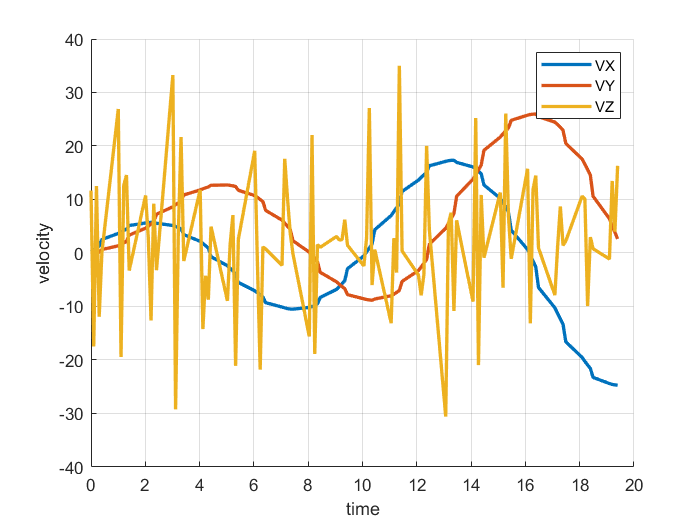


velocityVector = transpose(velocityVector);
time = transpose(time(1:end-1));

figure;
hold on;

plot(time, velocityVector(1,:), 'LineWidth', 2);
plot(time, velocityVector(2,:), 'LineWidth', 2);
plot(time, velocityVector(3,:), 'LineWidth', 2);

xlabel('time');
ylabel('velocity');
grid on;

legend('VX', 'VY', 'VZ');

function new_array = extract_every_third_column(R)
    new_array = R(:, 1:10:end);
end